% Example 3.1
% from Parameter Estimation and Inverse Problems, 3rd edition, 2018
% by R. Aster, B. Borchers, C. Thurber

% make sure we have a clean environment
clear

% Construct system matrix for the ray path models
s2=sqrt(2);
G = [1,0,0,1,0,0,1,0,0;
     0,1,0,0,1,0,0,1,0;
     0,0,1,0,0,1,0,0,1;
     1,1,1,0,0,0,0,0,0;
     0,0,0,1,1,1,0,0,0;
     0,0,0,0,0,0,1,1,1;
     s2,0,0,0,s2,0,0,0,s2;
     0,0,0,0,0,0,0,0,s2];

% Get the singular values for the system matrix
[U,S,V] = svd(G);

% Display singular values
disp('Singular values:')

Singular values:


diag(S)

ans =     3.1798
    2.0000
    1.7321
    1.7321
    1.7321
    1.6070
    0.5535
    0.0000



% Find dimensions of G
[m,n]=size(G);

% Find and display system rank
disp('System rank:')

System rank:


p=rank(G)

p = 7


% Display null space vectors 
disp('Model null space vectors')

Model null space vectors


V(:,p+1:n)

ans =     0.2681    0.3078
    0.3078   -0.2681
   -0.5760   -0.0397
   -0.3078    0.2681
   -0.2681   -0.3078
    0.5760    0.0397
    0.0397   -0.5760
   -0.0397    0.5760
   -0.0000   -0.0000



% Display null space vectors reshaped to match tomography example geometry
disp('Model null space vectors reshaped into matrices')

Model null space vectors reshaped into matrices


m01=reshape(V(:,p+1),3,3)'

m01 =     0.2681    0.3078   -0.5760
   -0.3078   -0.2681    0.5760
    0.0397   -0.0397   -0.0000


m02=reshape(V(:,p+2),3,3)'

m02 =     0.3078   -0.2681   -0.0397
    0.2681   -0.3078    0.0397
   -0.5760    0.5760   -0.0000



% Display image of null space model V.,8
figure(1)
clf
colormap('gray')
imagesc(m01)
caxis([-0.5 0.5]);
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Reshaped Null Space Model V.,8');
%bookfonts

disp('Displaying image of null space model V.,8 (fig. 1)')

Displaying image of null space model V.,8 (fig. 1)


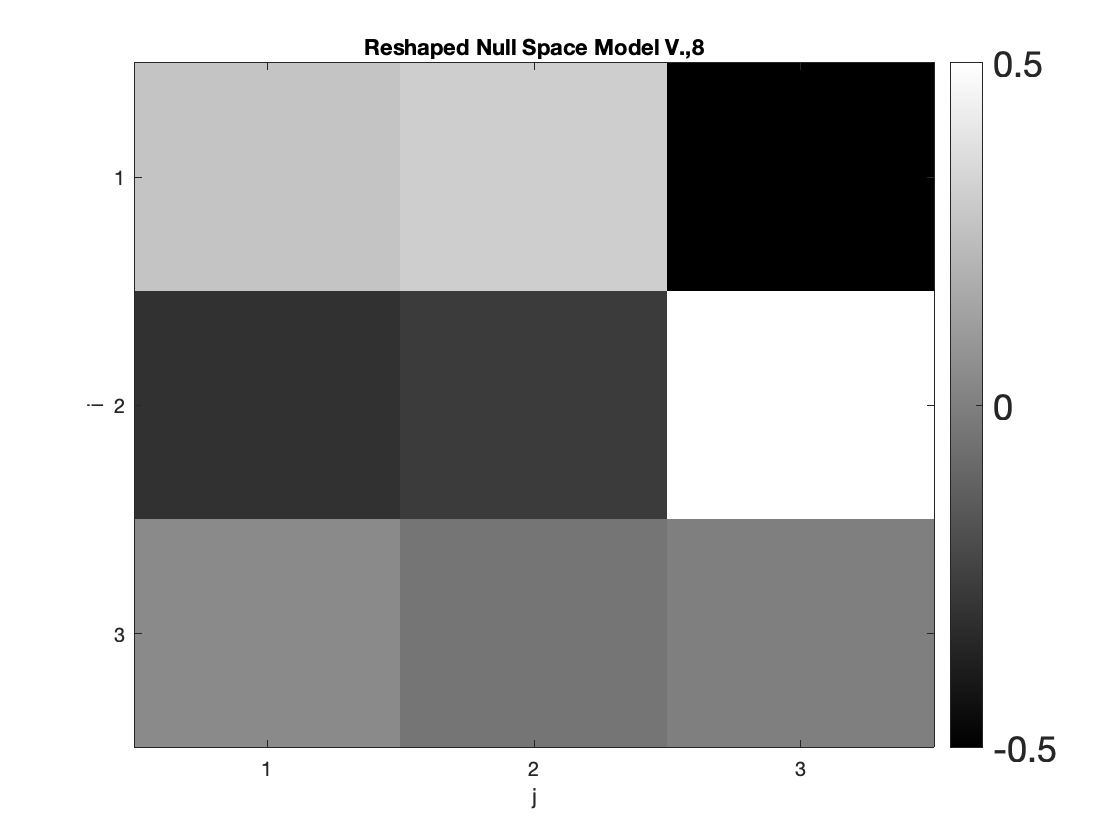

print -deps2 c3fv8null.eps


% Display image of null space model V.,9
figure(2)
clf
colormap('gray')
imagesc(m02)
caxis([-0.5 0.5]);
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Reshaped Null Space Model V.,9');
%bookfonts

disp('Displaying image of null space model V.,9 (fig. 2)')

Displaying image of null space model V.,9 (fig. 2)


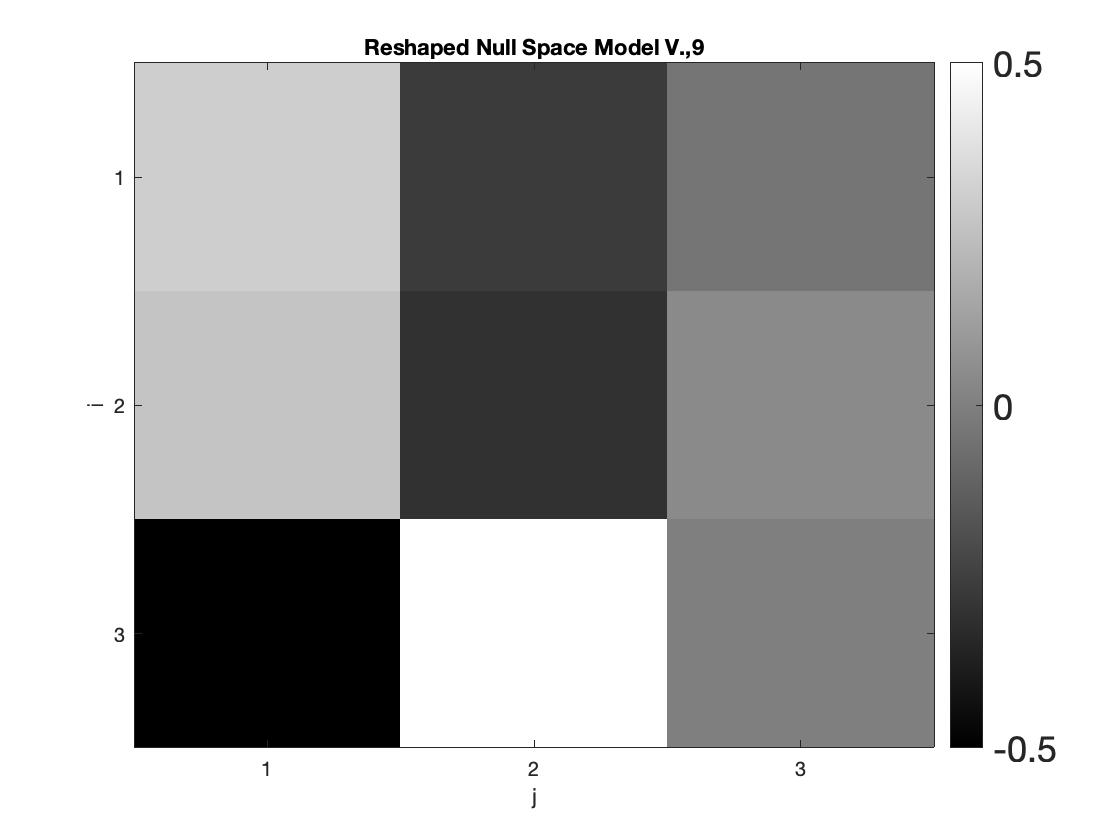

print -deps2 c3fv9null.eps


% Display data space null vector
disp('Data null space vector')

Data null space vector


U(:,p+1)

ans =     0.4082
    0.4082
    0.4082
   -0.4082
   -0.4082
   -0.4082
    0.0000
   -0.0000



% Find and display model resolution matrix
Vp=V(:,1:p);
Rm=Vp*Vp';

% Display full model resolution matrix and colorbar
figure(3)
clf
colormap('gray')
imagesc(Rm)
caxis([-0.1 1.0])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3,4,5,6,7,8,9]);
set(gca,'ytick',[1,2,3,4,5,6,7,8,9]);
xlabel('j')
ylabel('i')
title('Model Resolution Matrix')
%bookfonts

disp('Displaying full model resolution matrix (fig. 3)')

Displaying full model resolution matrix (fig. 3)


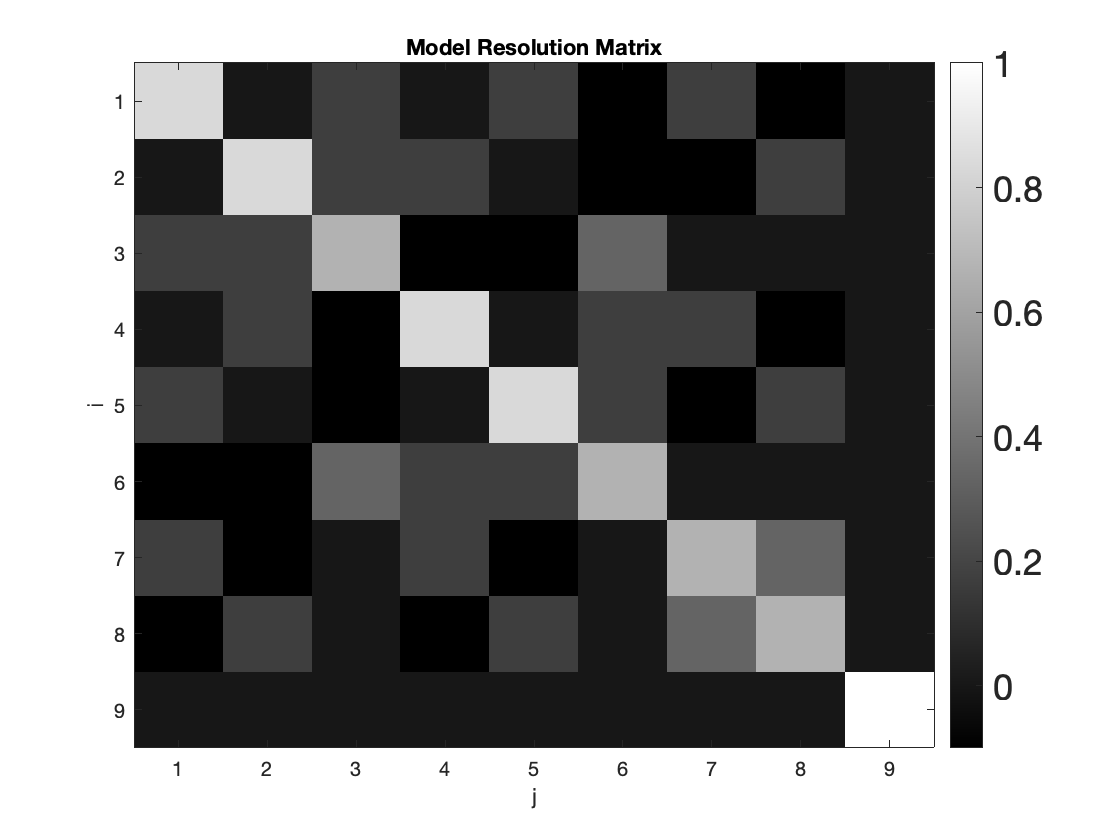

print -deps2 c3fR.eps


Rmdiag=reshape(diag(Rm),3,3)'

Rmdiag =     0.8333    0.8333    0.6667
    0.8333    0.8333    0.6667
    0.6667    0.6667    1.0000


% Display reshaped diagonal elements of the model resolution matrix and colorbar
figure(4)
clf
colormap('gray')
imagesc(Rmdiag)
caxis([-0.1 1.0])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Reshaped Model Resolution Matrix Diagonal Elements')
%bookfonts

disp('Displaying diagonal elements of model resolution matrix (fig. 4)')

Displaying diagonal elements of model resolution matrix (fig. 4)


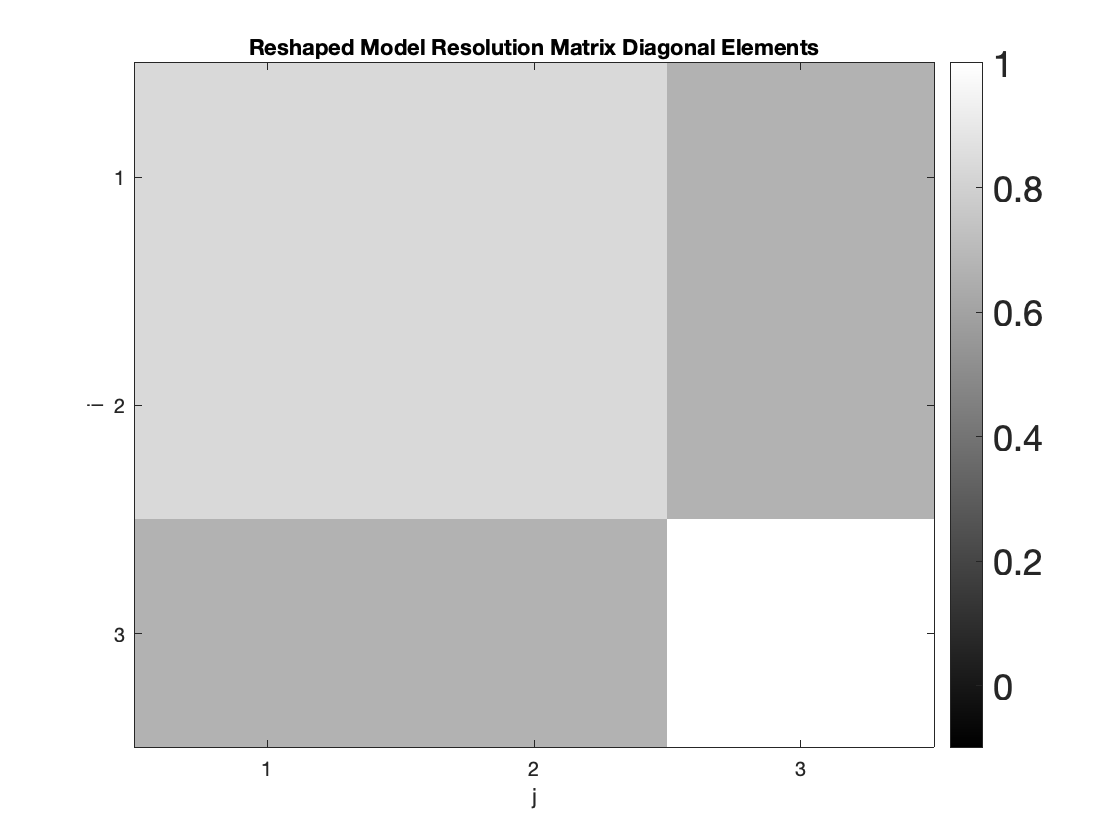

print -deps2 c3fRdiag.eps


% Spike resolution test
% Construct spike model
mtest=zeros(n,1);
mtest(5)=1;

% Get noise free data for the spike model (forward problem)
dtest=G*mtest;

% Display spike model and noise free data
disp('model spike and predicted data')

model spike and predicted data


mtest

mtest =      0
     0
     0
     0
     1
     0
     0
     0
     0


dtest

dtest =          0
    1.0000
         0
         0
    1.0000
         0
    1.4142
         0



% Display recovered model from spike test
disp('recovered model from the spike test')

recovered model from the spike test


% Let Matlab compute the psuedoinverse for us with pinv
mdagger=pinv(G)*dtest

mdagger =     0.1667
    0.0000
   -0.1667
   -0.0000
    0.8333
    0.1667
   -0.1667
    0.1667
    0.0000



% Display reshaped noise free spike model with color bar
figure(5)
clf
colormap('gray')
imagesc(reshape(mtest,3,3))';
caxis([-0.1 1.0])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Spike Test Model')
%bookfonts

disp('Displaying spike test model (fig. 5)')

Displaying spike test model (fig. 5)


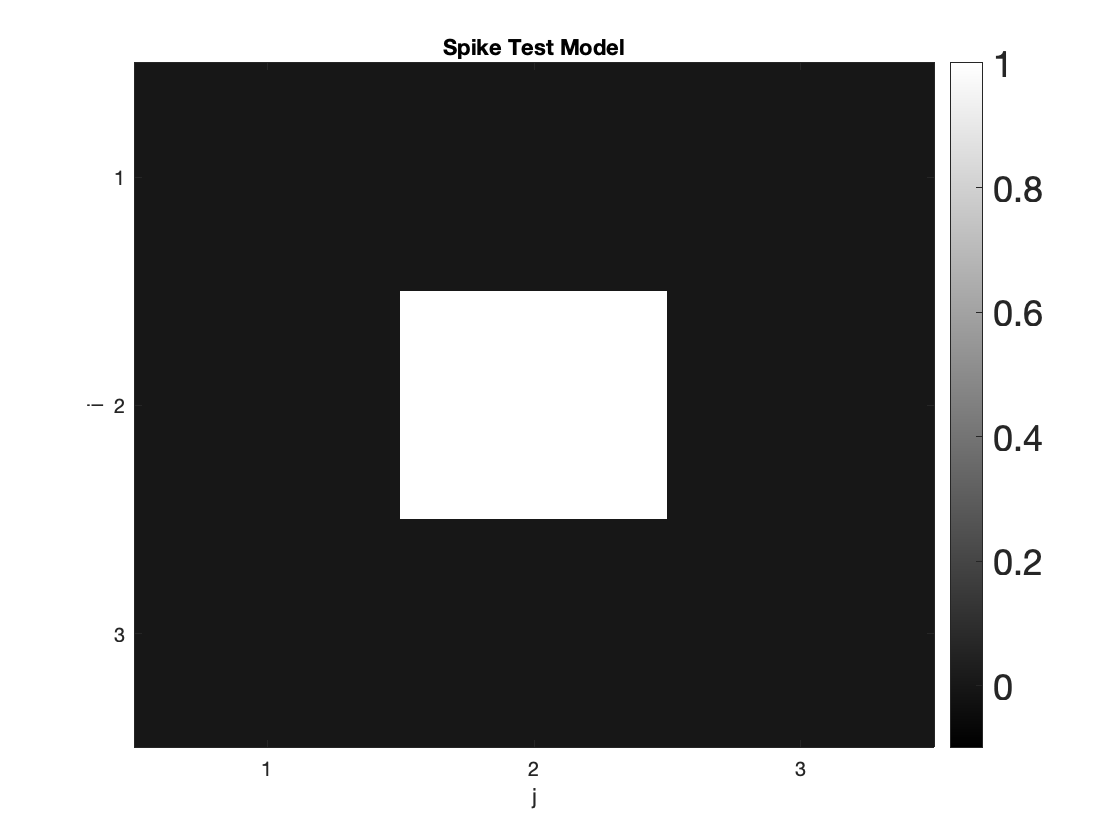

print -deps2 c3fspike.eps


% Display reshaped recovered spike model with colorbar
figure(6)
clf
colormap('gray')
imagesc(reshape(mdagger,3,3)');
caxis([-0.1 1.0])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Recovered Model from Spike Test Model Data')
%bookfonts

disp('Displaying recovered model from noise-free spike test data (fig. 6)')

Displaying recovered model from noise-free spike test data (fig. 6)


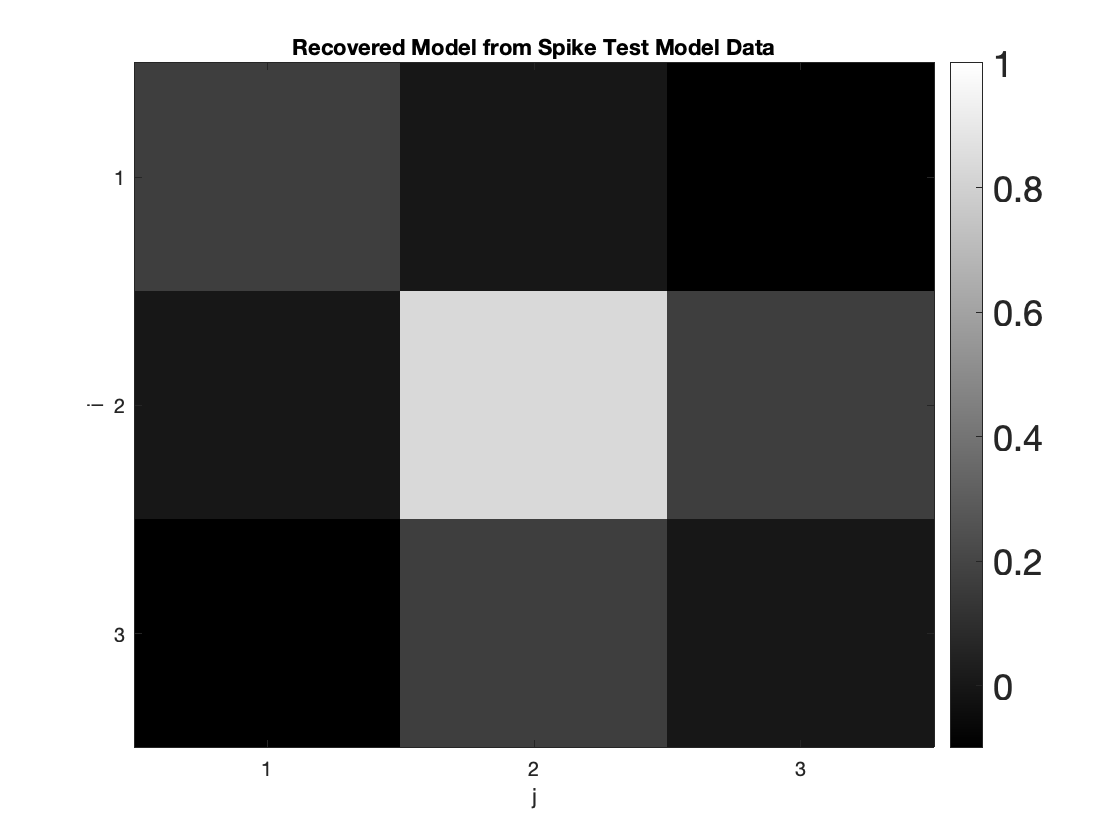

print -deps2 c3fspike_recov.eps